# EECE 5580 Classical Control Systems - Take Home Exam

- Open book exam

- First complete on my own and then consult will classmates

- Log # of days of work and revising with classmates

- Have fun :D

## Twin-Rotor Aerodynamic Propulsion System (TWR)

- Professor has provided a table of the TWR Frequency Response (open-loop) across a finite-length of frequencies. 

- Answer and complete the following assigned tasks using Table 1

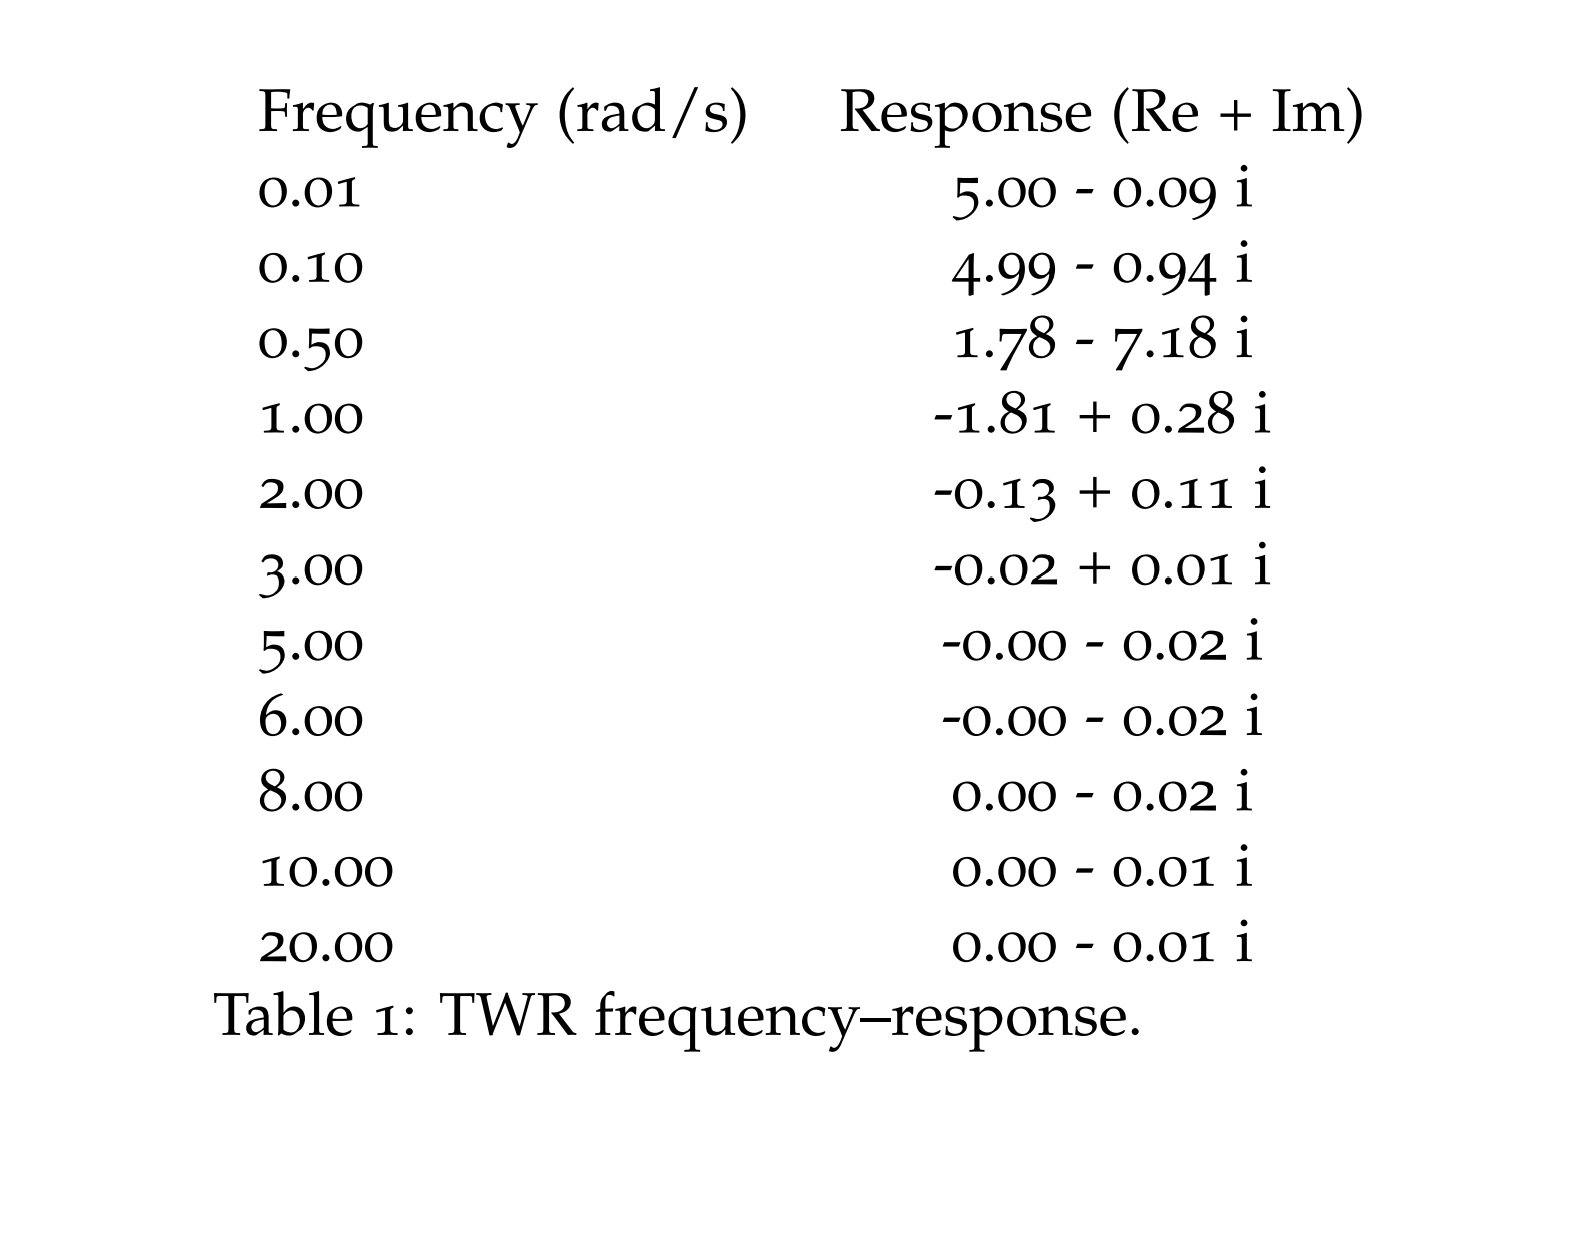

clc; close all; clear;
f = imread('Table_1.png');figure,imshow(f),pause(1)

gReal = [5 4.99 1.78 -1.81 -0.13 -0.02 -0.00 -0.00 0.00 0.00 0.00];
gImag = [-0.09 -0.94 -7.18 0.28 0.11 0.01 -0.02 -0.02 -0.02 -0.01 -0.01];
G = gReal + 1i*gImag; omega = [1/100 1/10 1/2 1 2 3 5 6 8 10 20]; 

### 1.) Plot Points and Generate Approximate TWR Bode Plot

numPoles = 3;
sys = frd(G,omega), PsysEst = tfest(sys,numPoles);

sys =
 
    Frequency(rad/s)         Response    
    ----------------         --------    
          0.0100         5.0000 - 0.0900i
          0.1000         4.9900 - 0.9400i
          0.5000         1.7800 - 7.1800i
          1.0000        -1.8100 + 0.2800i
          2.0000        -0.1300 + 0.1100i
          3.0000        -0.0200 + 0.0100i
          5.0000        -0.0000 - 0.0200i
          6.0000        -0.0000 - 0.0200i
          8.0000         0.0000 - 0.0200i
         10.0000         0.0000 - 0.0100i
         20.0000         0.0000 - 0.0100i
 
Continuous-time frequency response.



num = PsysEst.Numerator, denom = PsysEst.Denominator

num =     0.1677    0.1300    2.0270


denom =     1.0000    1.3976    0.7751    0.4054


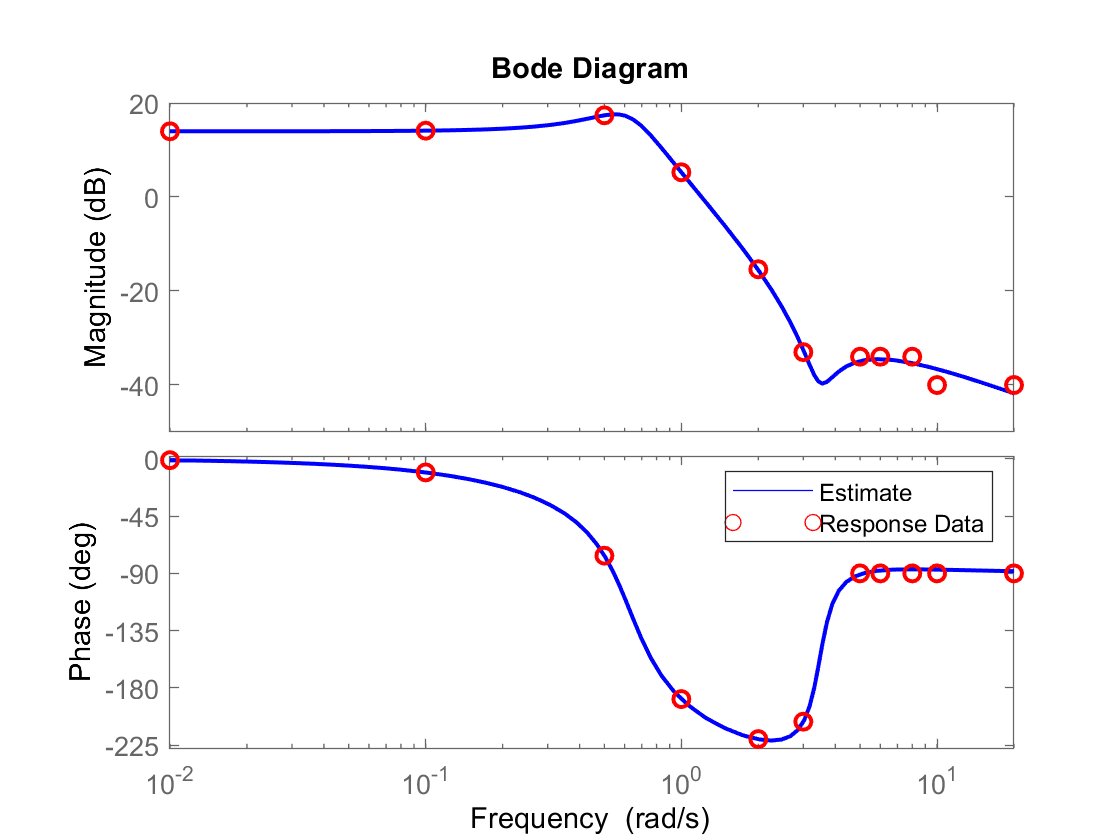

opt = bodeoptions('cstprefs');
opt.MagLowerLimMode = 'manual';
opt.MagLowerLim = -50;
figure, bode(PsysEst,opt,'b'), hold on, bode(sys,omega,opt,'ro'), hold off
hL = findobj(gcf,'type','line'); legend('Estimate','Response Data')
set(hL,'linewidth',1.5); 

### 2.) Obtain a Transfer Function for the Model

zpkModel =
 
   0.16774 (s^2 + 0.7751s + 12.08)
  ----------------------------------
  (s+1.027) (s^2 + 0.3704s + 0.3947)
 
Continuous-time zero/pole/gain model.



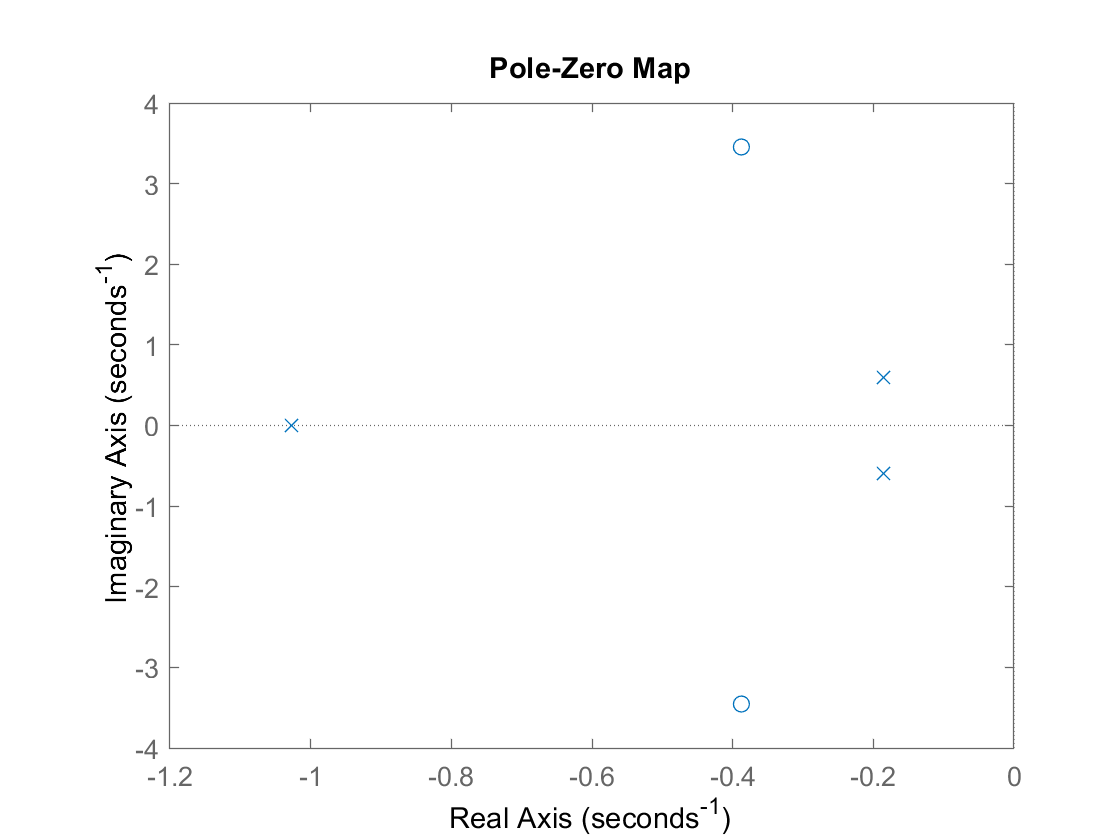

zpkModel = zpk(PsysEst), pzmap(zpkModel)

### 3.) Trace Root Locus and Nyquist Plot 

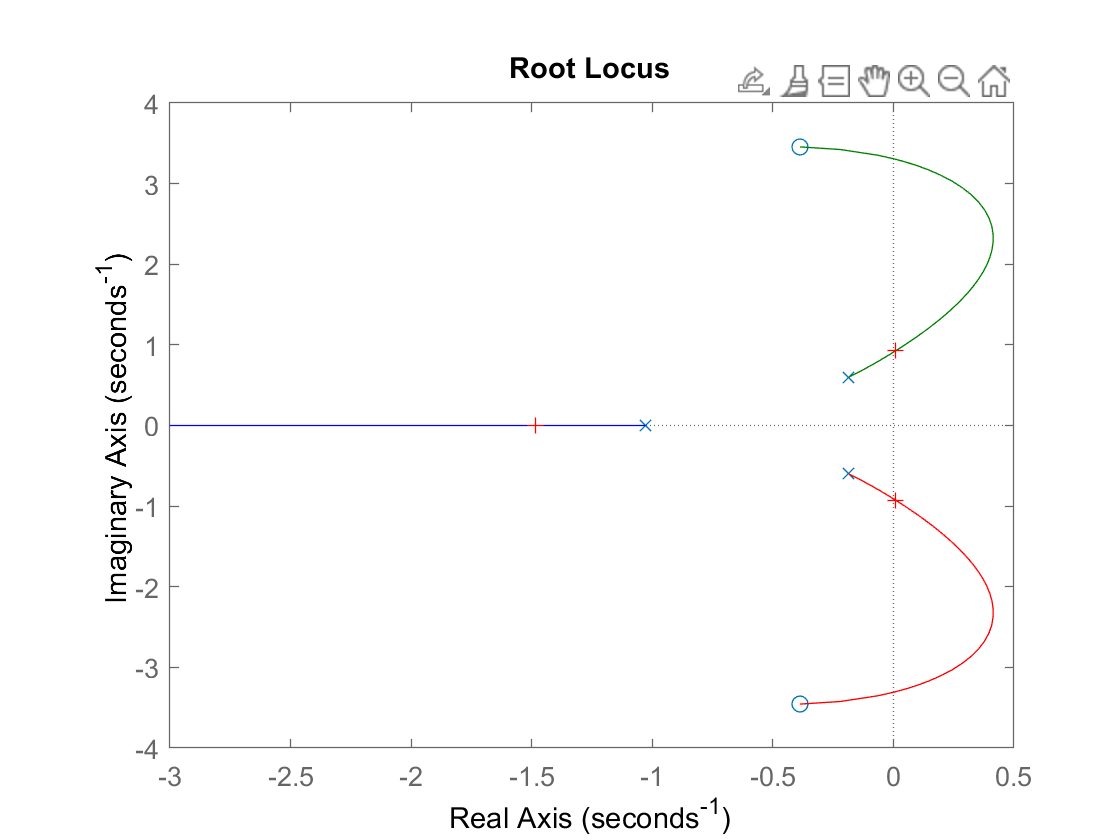

Select a point in the graphics window


selected_point = -0.0039 + 0.9302i

k = 0.4257

poles =   -1.4849 + 0.0000i
   0.0080 + 0.9241i
   0.0080 - 0.9241i


figure, rlocus(PsysEst)
[k,poles] = rlocfind(PsysEst)

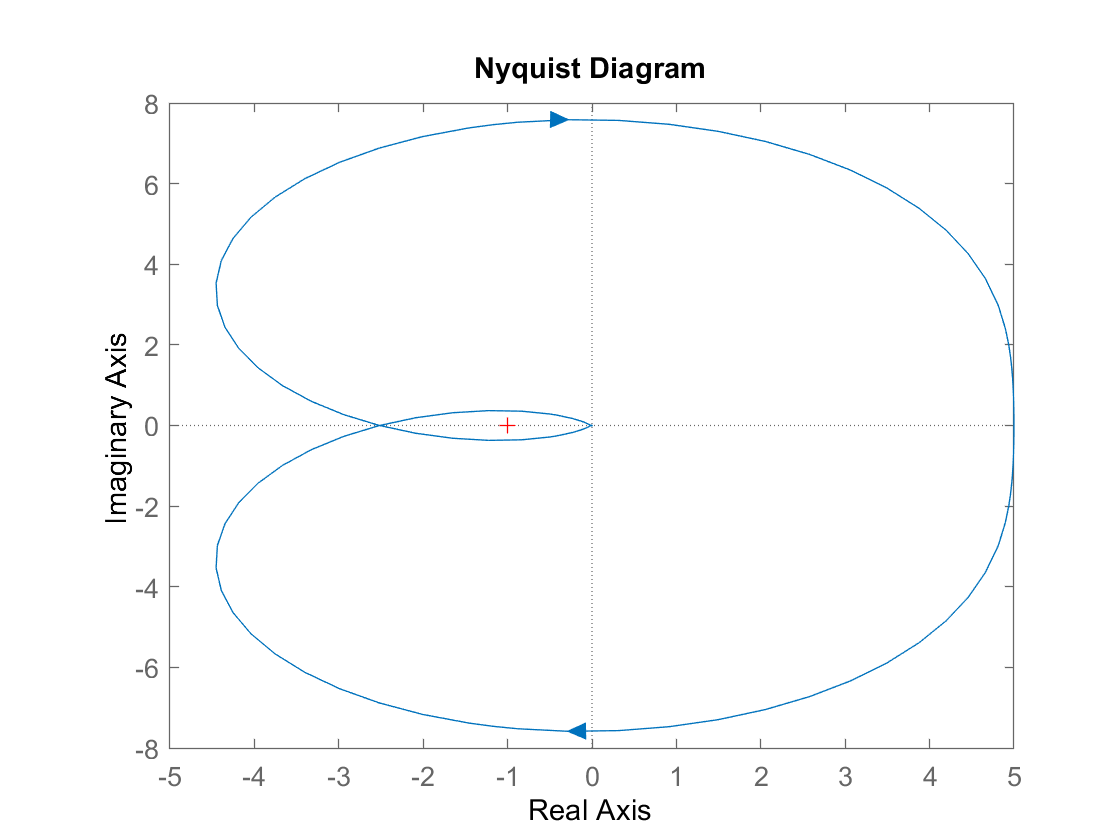

figure, nyquist(PsysEst), xticks([-5:1:5])

### 4.) Discuss Qualitatively the Stability/Performance of CL System

After performing Root Locus analysis, I've calculated that the system has 3 poles, one real and one pair of complex poles, and two zeros. When performing the root locus the system will become unstable if a Open-Loop Proportional Gain factor of about $k=0\ldotp 4257$ is combined with the system.

The system has one set of complex pole pairs, with the pair that will cross the Imaginary axis making the system unstable when the gain is between $0.4257\leq k \leq 73.9411$

The single real pole of the system is at $p = -1.4849$ and will approach $- \infty$ as the gain is continuously increased.

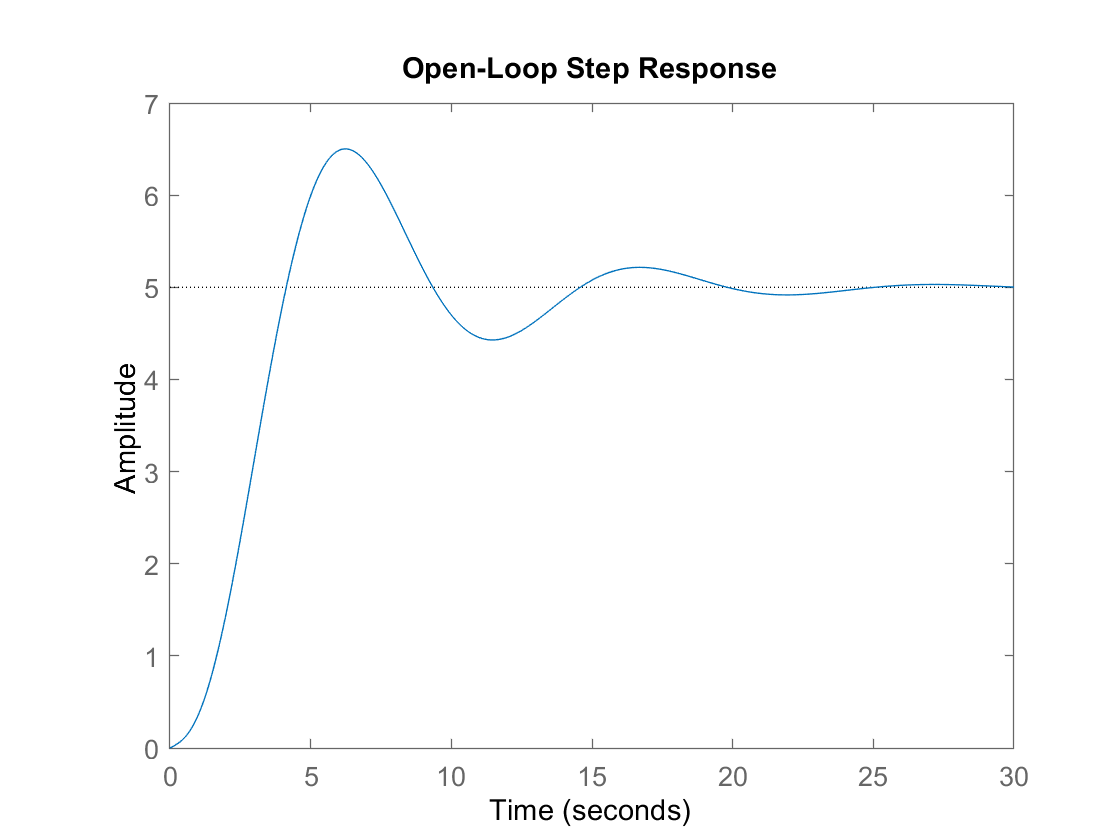

figure, step(PsysEst), title('Open-Loop Step Response')

The Nyquist plot shows that the Transfer Function $G(s)$ goes to zero as $s$ gets large and then the segement of the contour at infinity maps back to the origin.

We can also see that the system displays unstable characterisitics as the transfer function provides an encirclement around the critical point of $s = -1$. From here, we must design a controller that can reign in the transfer function and ultimately make the system stable. 

### 5.) Suggest Potential Controller (PID, Lead-Lag, Pole-Assignment)

The potential controller I think will help resolve the Open-Loop Step response would be a **PID Controller**. The reason I'm choosing this controller is because each term of the PID Controller, $K_p$, $K_i$, and $K_d$ can all contribute to a goal of 

- Fast rise time

- Minimal overshoot

- Zero Steady-state error

### 6.) Design and Analyze System with Controller Implemented

#### PID Control

% Use pidtune() function to derive another controller
P = PsysEst; % Plant
C = pidtune(P,'PID') % Controller

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.139, Ki = 0.0427, Kd = 0.113
 
Continuous-time PID controller in parallel form.



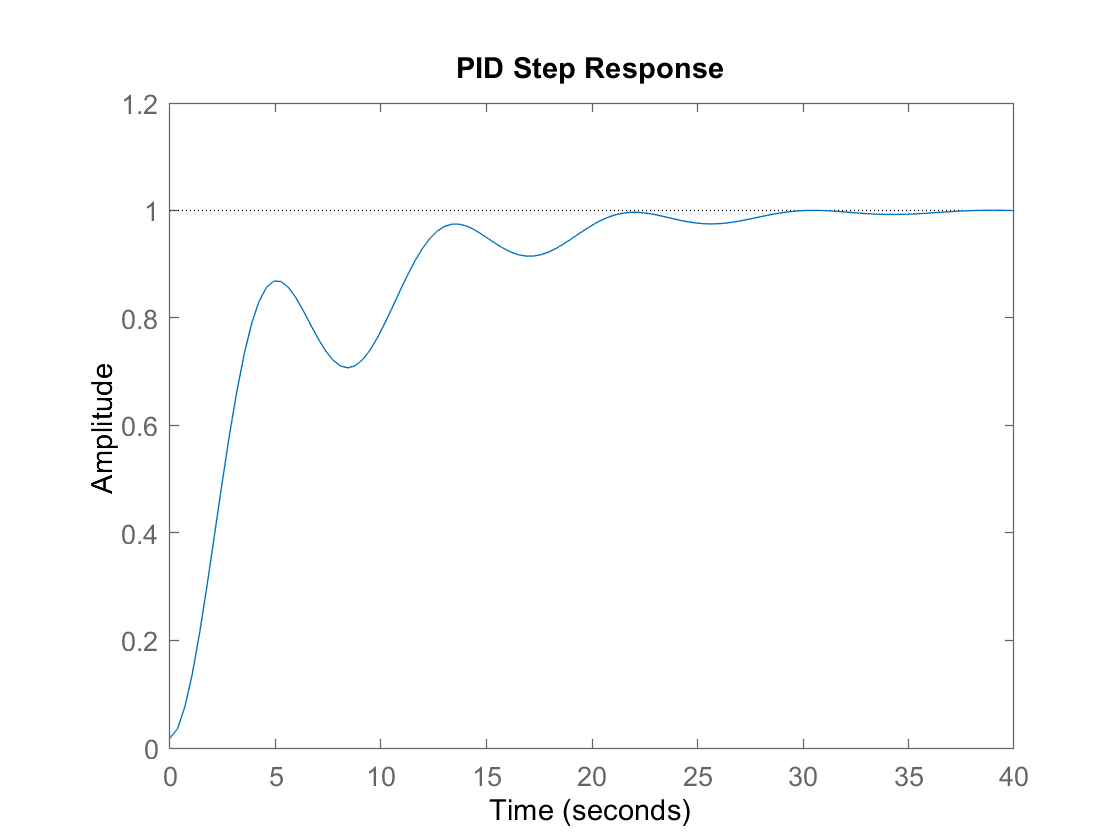

Y = feedback(series(C,P),1); % Create Feeback Loop with Open-Loop
figure, step(Y), title('PID Step Response')

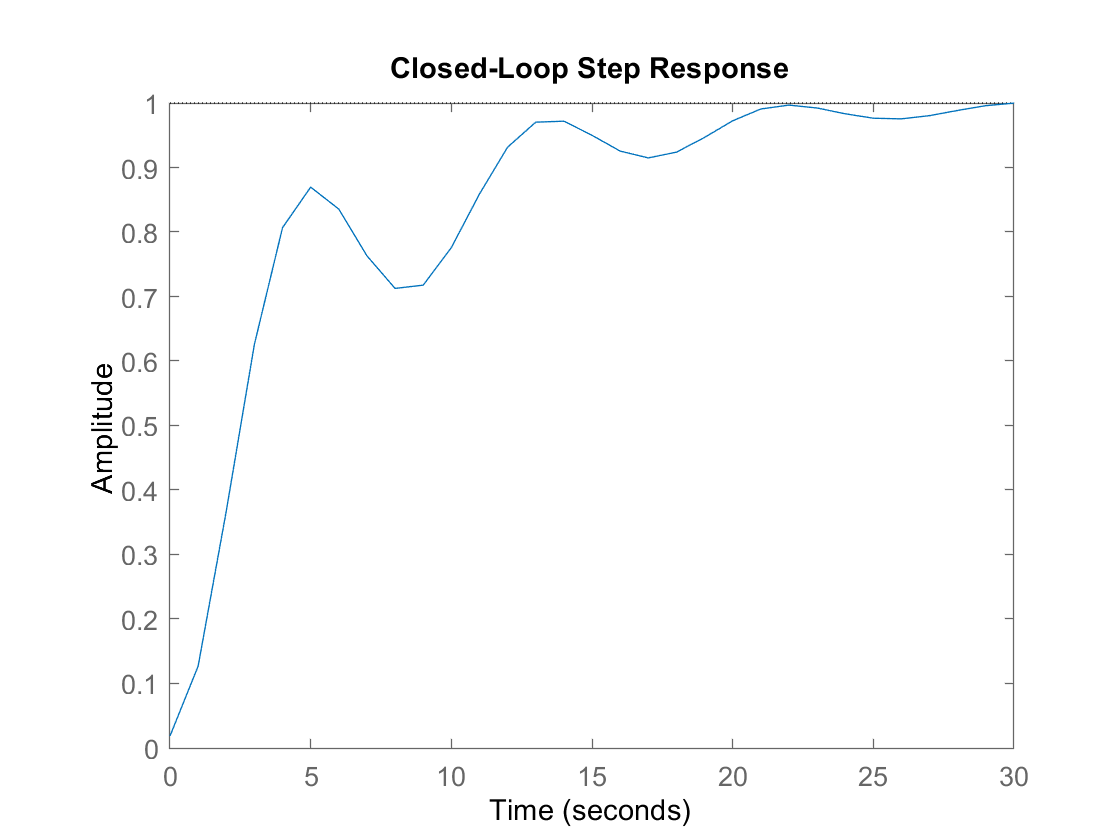

figure, t = 0:30; step(Y,t), title('Closed-Loop Step Response')

#### Stability

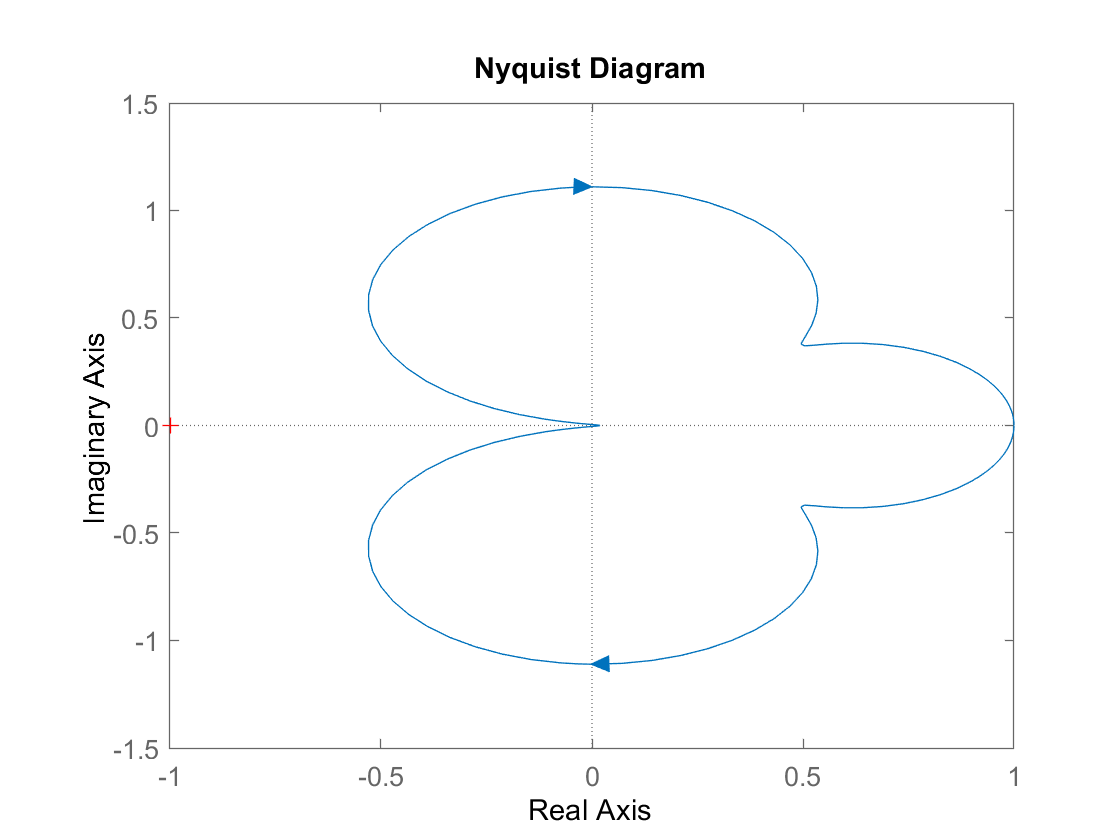

figure, nyquist(Y)

PID_Stable = isstable(Y)

PID_Stable = logical
   1


Here we can see from Closed-Loop Step Response that the system now has been resolved of the open-loop system's stability issues, as the output after using the isstable() function, provides a reassurance that the controller resolved the encirclement of the critical point. The closed-loop step response is rather slow as it takes almost 30 secs to reach the steady state, but there is no overshoot that results from the controller.

### 7.) Alter the Response Data and Verify Controller Still Works

% Add random noise to the original data and test the controller's
% performance for stability 
gReal = [5 4.99 1.78 -1.81 -0.13 -0.02 -0.00 -0.00 0.00 0.00 0.00];
gImag = [-0.09 -0.94 -7.18 0.28 0.11 0.01 -0.02 -0.02 -0.02 -0.01 -0.01];
rng(1);
realNoise = rand([1,11]);
imagNoise = rand([1,11]);
gReal = gReal + realNoise;
gImag = gImag + imagNoise;
G = complex(gReal,gImag); omega = [1/100 1/10 1/2 1 2 3 5 6 8 10 20];
numPoles = 3;
sys = frd(G,omega), sysEst = tfest(sys,numPoles);

sys =
 
    Frequency(rad/s)         Response    
    ----------------         --------    
          0.0100         5.4170 + 0.5952i
          0.1000         5.7103 - 0.7355i
          0.5000         1.7801 - 6.3019i
          1.0000        -1.5077 + 0.3074i
          2.0000         0.0168 + 0.7805i
          3.0000         0.0723 + 0.4273i
          5.0000         0.1863 + 0.5387i
          6.0000         0.3456 + 0.1204i
          8.0000         0.3968 + 0.1781i
         10.0000         0.5388 + 0.7907i
         20.0000         0.4192 + 0.9583i
 
Continuous-time frequency response.



num = sysEst.Numerator, denom = sysEst.Denominator

num =   -11.1153   11.0679  -26.3614


denom =     1.0000  -12.9420   -6.1656   -4.9058


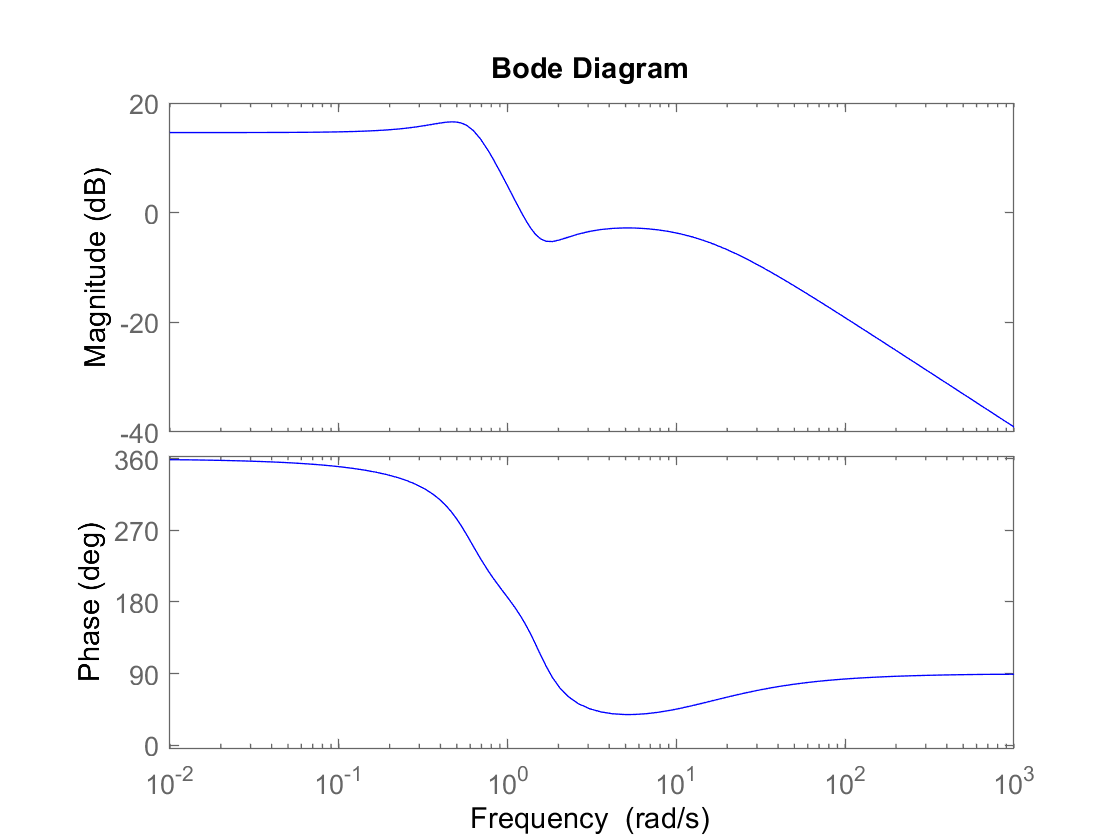

figure, bode(sysEst,'b')

zpkModel =
 
   -11.115 (s^2 - 0.9957s + 2.372)
  ----------------------------------
  (s-13.43) (s^2 + 0.4864s + 0.3653)
 
Continuous-time zero/pole/gain model.



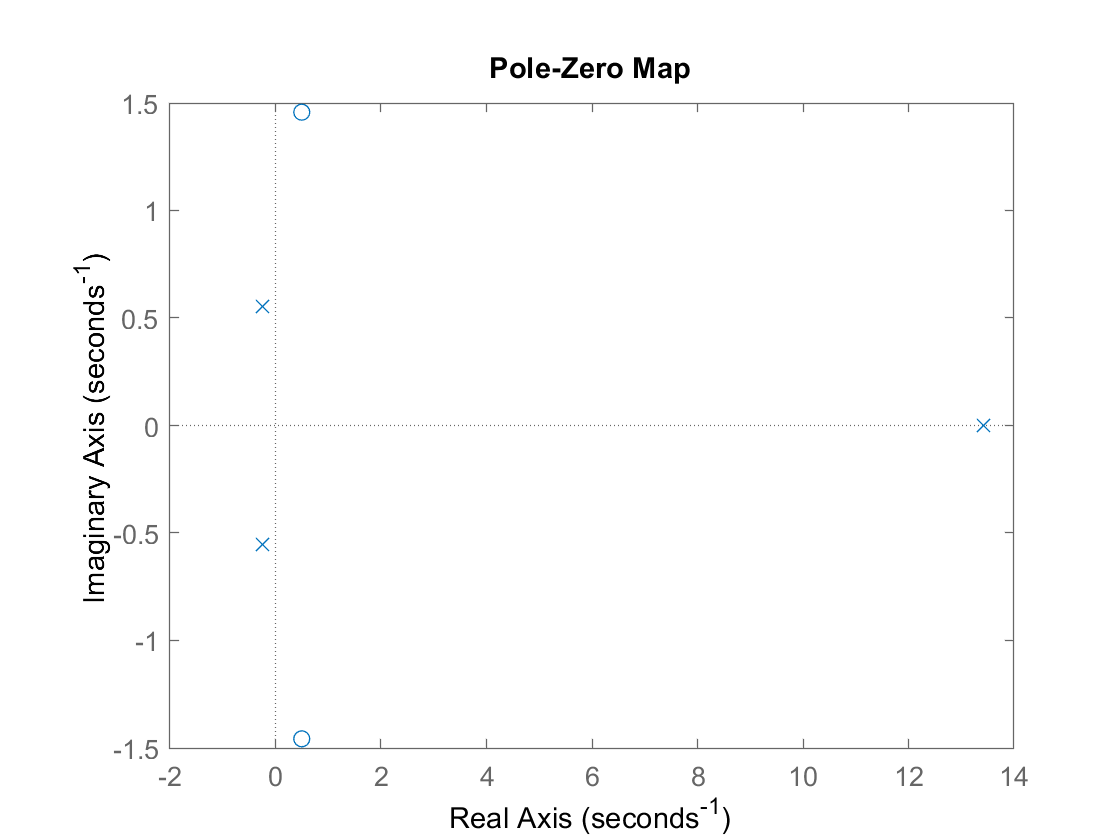

zpkModel = zpk(sysEst), pzmap(zpkModel)

Here, I've added random values to the original dataset of values given to us, to test the performance of the controller to find out if it has a certain level of robustness such that it can also stabilize another Plant with similar but different values than the previous parts. 

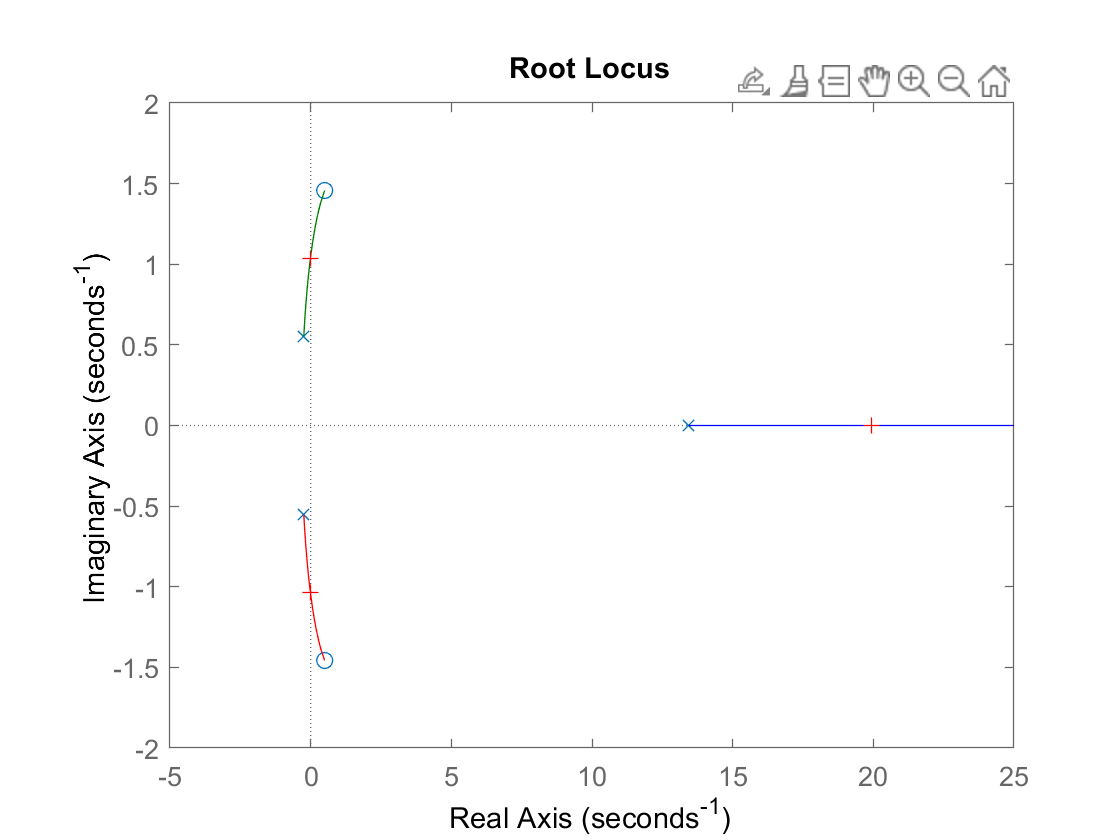

Select a point in the graphics window


selected_point = -0.0059 + 1.0357i

k = 0.6265

poles =   19.9212 + 0.0000i
  -0.0077 + 1.0369i
  -0.0077 - 1.0369i


figure, rlocus(sysEst)
[k,poles] = rlocfind(sysEst)

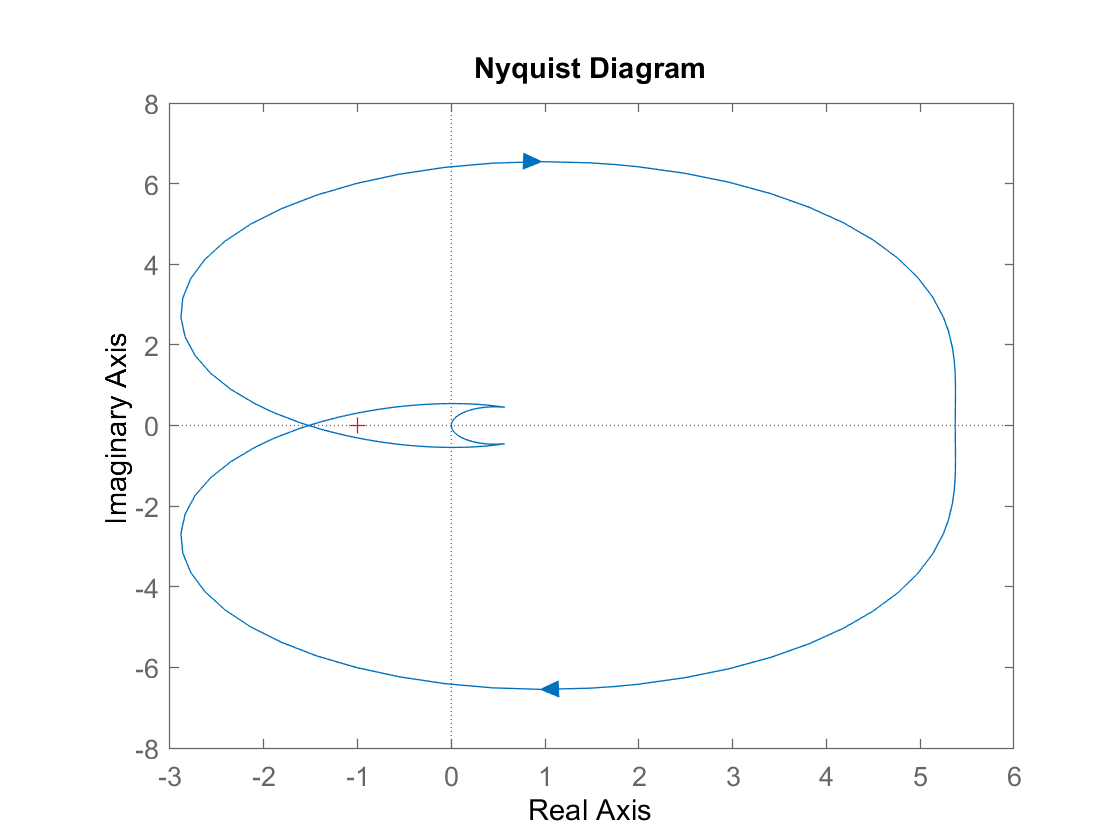

figure, nyquist(sysEst)

We can see that this new set of data contains an encirclement of the critical point, and shows that the added random noise did not alter the original stability issues. Now we must show whether the controller that was designed in the previous sections can also stabilize this new Plant system.

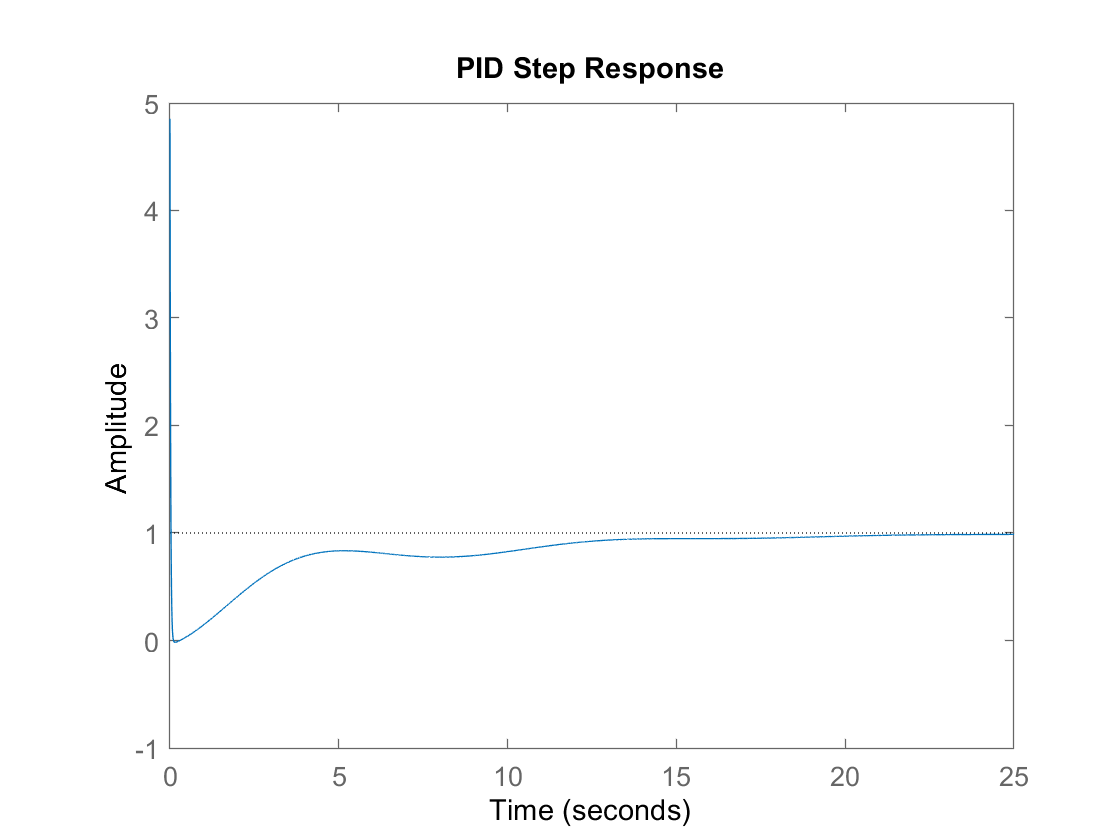

% Use pidtune() function to derive another controller
P = sysEst; % Plant 
Y = feedback(series(C,P),1); % Create Feeback Loop with Open-Loop
figure, step(Y), title('PID Step Response')

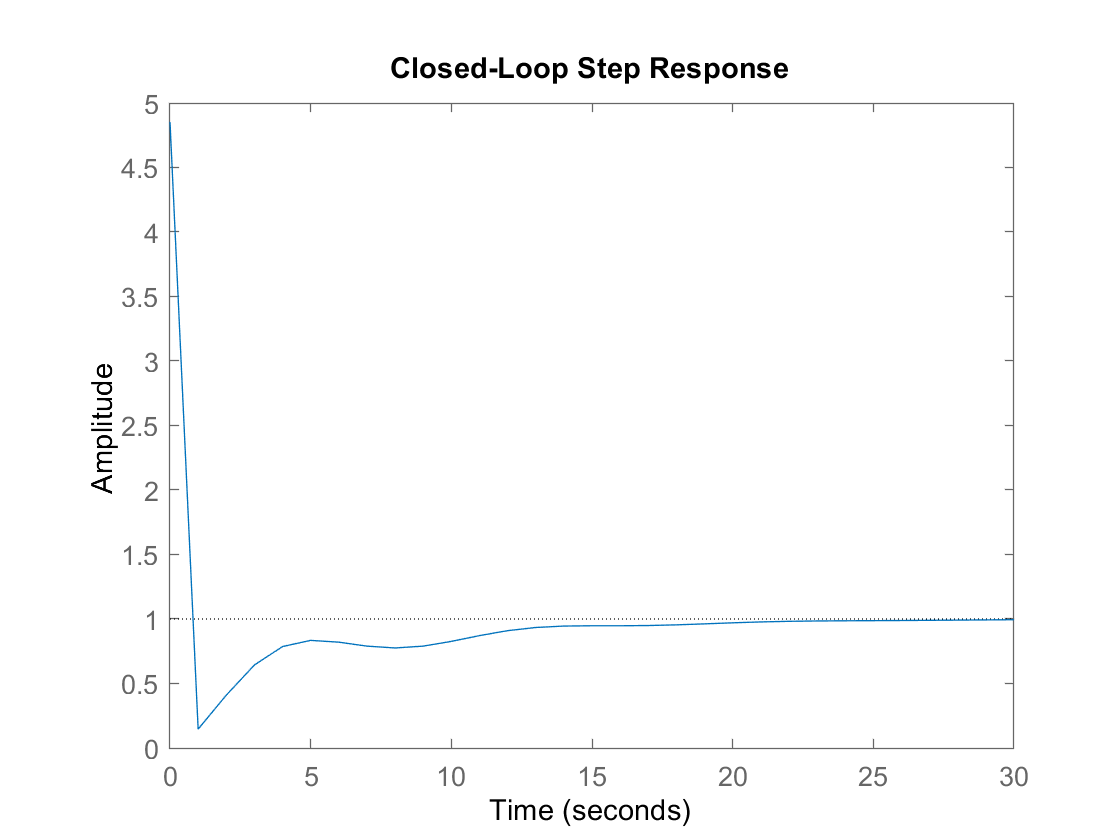

figure, t = 0:30; step(Y,t), title('Closed-Loop Step Response')

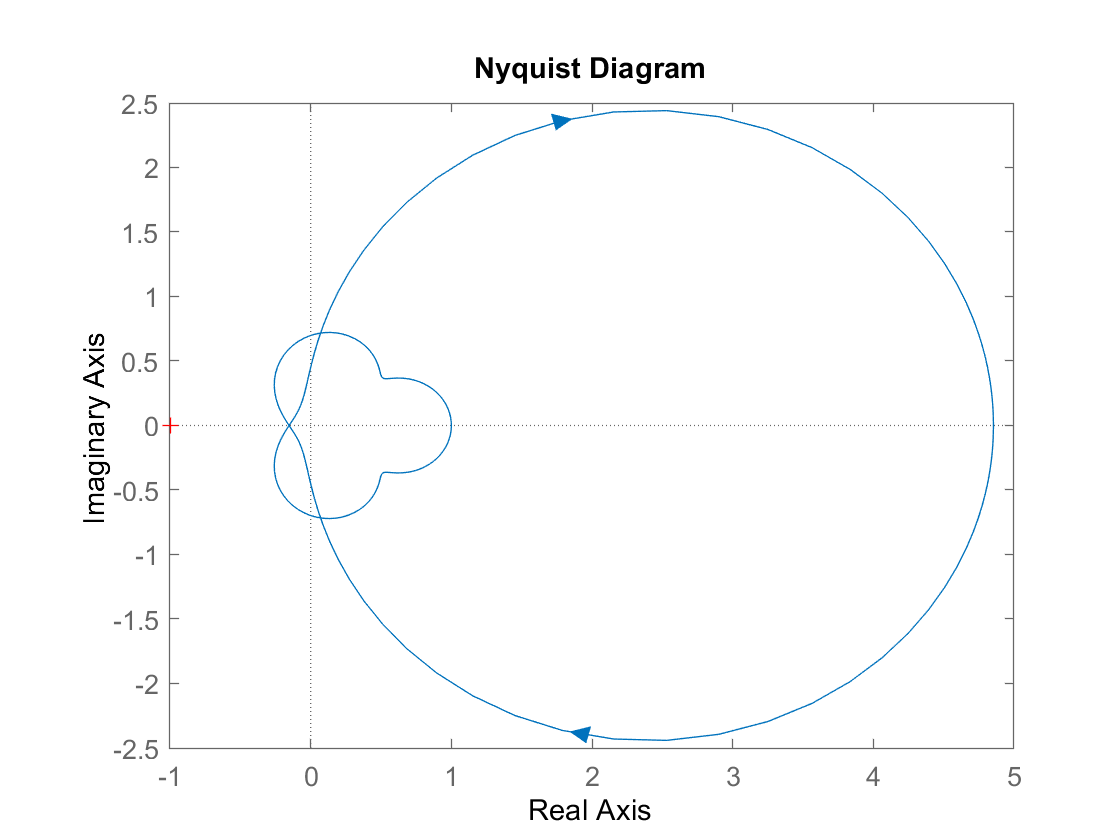

figure, nyquist(Y)

PID_stable = isstable(Y)

PID_stable = logical
   1


We can observe that using the same controller that was designed in Part 6.) has produced a closed-loop step response that reaches a steady-state after about 25 seconds and the nyquist diagram no longer contains an encirclement of the critical point. For verification, I used the isstable() function to check whether this output had become stable as a result of combining it to the new closed-loop system with added random noise, and the system in fact remains stable in it's output. 

### 8.) (Extra Credit) Process is not Minimum-Phase and Measurements of Gain in several frequencies missed an Allpass-Factor of $\frac{1 - Ts}{1 + Ts}$ Explain and Pick a numerical value of $T$ and redesign your controller as needed. 

# Conclusion

I was able to design a controller that stabilizes the TWR Plant system response in the closed-loop orientation for both original dataset values in addition to providing added random noise to the original values.

In total, I would say this Take Home Exam took me about 4-5 days of looking up MATLAB functions, referencing lecture notes, and performing the necessary analysis to come up with my solutions. 

Having a single day during lecture hours provided some insight on how other classmates approached this problem, and helped solidfy that the results I was able to derive were on the correct path or contained proper demonstration of the classical controls analysis tools we have worked with and learned about throughout the entire semester.  